# Lab 8

Jessie Li // November 15, 2023

## 1

### a.

L = 1;
lambda2 = 2.7;
Ta = 37;
Tc = 37;
Ts = 32;

T_analytic = @(x) (Ts - Tc) .* sinh(sqrt(lambda2) .* x) ./ sinh(sqrt(lambda2) * L);
n_subintervals = [5, 10, 20, 40, 80, 160];


errors_lu = zeros(1, size(n_subintervals, 2));

figure 
default_style()

hold on

% Plot analytic solution
xx = 0 : 1e-3 : L;
plot(xx, T_analytic(xx), 'magenta', 'LineWidth', 2, 'DisplayName', 'Analytic')

for j = 1 : size(n_subintervals, 2)
    n = n_subintervals(j) - 1;

    % Construct system of finite difference equations
    [A, b, h] = finite_difference_matrix(n);

    % Solve the system for T = [T1 ... Tn]
    T = solve_tridiagonal(A, b);

    % Plot T v. x
    xx = 0 : h : L;
    TT = [(Tc - Ta) T.' (Ts - Ta)];

    plot(xx, TT, '--', 'LineWidth', 2, 'DisplayName', sprintf('N + 1 = %d', n + 1));

    % Calculate error
    errors_lu(j) = max(abs(TT - T_analytic(xx)));
    max(abs(TT - T_analytic(xx)))

end

ans = 0.0048

ans = 0.0012

ans = 3.0349e-04

ans = 7.5931e-05

ans = 1.8998e-05

ans = 4.7496e-06

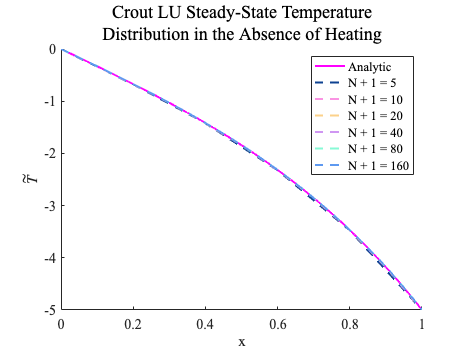


hold off

xlabel('x', 'Interpreter', 'latex')
ylabel('$\tilde{T}$', 'Interpreter', 'latex')
title({'Crout LU Steady-State Temperature', 'Distribution in the Absence of Heating'}, 'FontWeight', 'normal', 'FontSize', 18)

legend()

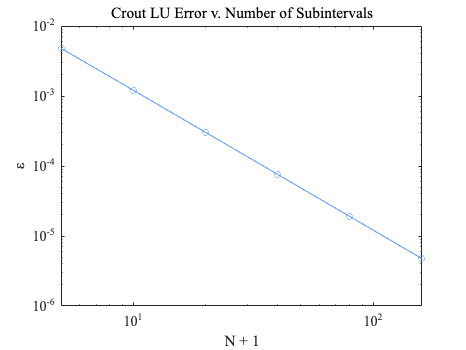

% Plot ε versus (N + 1) on a log-log scale
figure
default_style()

loglog(n_subintervals, errors_lu, '-o')

ylabel('ε')
xlabel('N + 1')
title({'Crout LU Error v. Number of Subintervals'}, 'FontWeight', 'normal', 'FontSize', 18)

### b.

N + 1 = 5: Gauss-Seidel converged after 11 iterations.
N + 1 = 10: Gauss-Seidel converged after 12 iterations.
N + 1 = 20: Gauss-Seidel converged after 50 iterations.
N + 1 = 40: Gauss-Seidel converged after 54 iterations.
N + 1 = 80: Gauss-Seidel converged after 137 iterations.
N + 1 = 160: Gauss-Seidel converged after 194 iterations.


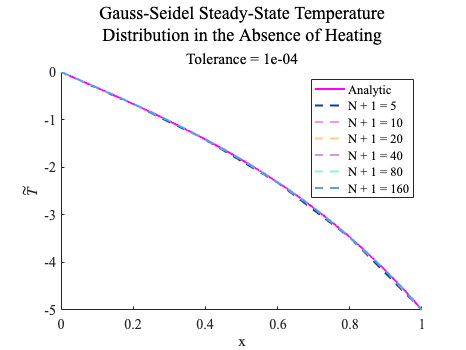

N + 1 = 5: Gauss-Seidel converged after 15 iterations.
N + 1 = 10: Gauss-Seidel converged after 31 iterations.
N + 1 = 20: Gauss-Seidel converged after 127 iterations.
N + 1 = 40: Gauss-Seidel converged after 288 iterations.
N + 1 = 80: Gauss-Seidel converged after 377 iterations.
N + 1 = 160: Gauss-Seidel converged after 515 iterations.


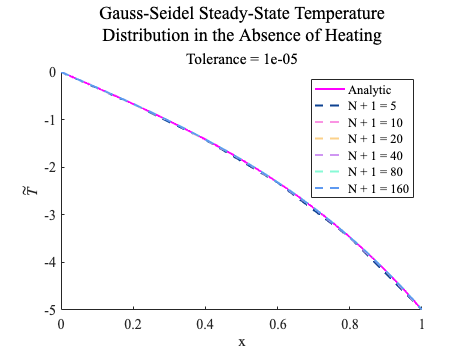

N + 1 = 5: Gauss-Seidel converged after 19 iterations.
N + 1 = 10: Gauss-Seidel converged after 49 iterations.
N + 1 = 20: Gauss-Seidel converged after 200 iterations.
N + 1 = 40: Gauss-Seidel converged after 576 iterations.
N + 1 = 80: Gauss-Seidel converged after 996 iterations.
N + 1 = 160: Gauss-Seidel converged after 1486 iterations.


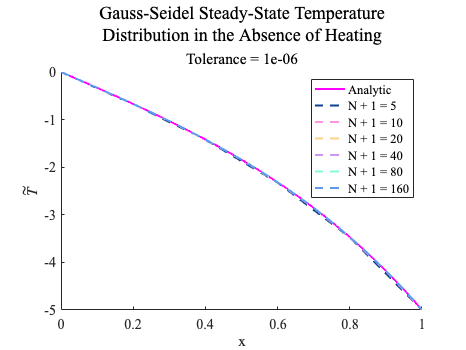

tolerances = [1e-4, 1e-5, 1e-6];
max_iterations = 2000;

errors_gauss_seidel = zeros(size(tolerances, 2), size(n_subintervals, 2));
estimate_spectral_radii = zeros(size(tolerances, 2), size(n_subintervals, 2));
spectral_radii = zeros(1, size(n_subintervals, 2));

for t = 1 : size(tolerances, 2)
    tolerance = tolerances(t);

    figure 
    default_style()

    hold on

    % Plot analytic solution
    xx = 0 : 1e-3 : L;
    plot(xx, T_analytic(xx), 'magenta', 'LineWidth', 2, 'DisplayName', 'Analytic')

    for j = 1 : size(n_subintervals, 2)
        n = n_subintervals(j) - 1;

        % Construct system of finite difference equations
        [A, b, h] = finite_difference_matrix(n);

        % Initial guess for Gauss-Seidel (analytic + random offset)
        rng(0)
        T0 = T_analytic(h:h:L-h).' + (-0.05 + 0.1*rand(n,1));
        
        % Use Gauss-Seidel to solve the system for T = [T1 ... Tn]
        [T, estimate_spectral_radii(t, j)] = gauss_seidel(A, b, T0, tolerance, max_iterations);

        % Plot T v. x
        xx = 0 : h : L;
        TT = [(Tc - Ta) T.' (Ts - Ta)];

        plot(xx, TT, '--', 'LineWidth', 2, 'DisplayName', sprintf('N + 1 = %d', n + 1));

        % Calculate error
        errors_gauss_seidel(t, j) = max(abs(TT - T_analytic(xx)));
        % max(abs(TT - T_analytic(xx)))

        if t == 1
            % Calculate exact spectral radius
            spectral_radii(j) = spectral_radius(A);
        end
  
    end

    hold off

    xlabel('x', 'Interpreter', 'latex')
    ylabel('$\tilde{T}$', 'Interpreter', 'latex')
    title({'Gauss-Seidel Steady-State Temperature', 'Distribution in the Absence of Heating'}, 'FontWeight', 'normal', 'FontSize', 18)
    subtitle(sprintf('Tolerance = %1.0e', tolerances(t)), 'FontWeight', 'normal', 'FontSize', 16)
    legend()
end

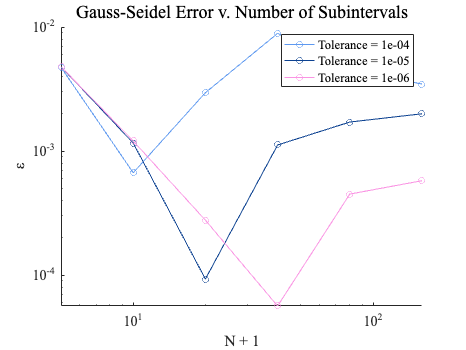

% Plot ε versus (N + 1) on a log-log scale for various tolerances
figure
default_style()

hold on
for i = 1 : size(tolerances, 2)
    plot(n_subintervals, errors_gauss_seidel(i, :), '-o', 'DisplayName', sprintf('Tolerance = %1.0e', tolerances(i)));
end
hold off

set(gca, 'YScale', 'log', 'XScale', 'log');

ylabel('ε')
xlabel('N + 1')
title({'Gauss-Seidel Error v. Number of Subintervals'}, 'FontWeight', 'normal', 'FontSize', 18)

legend()

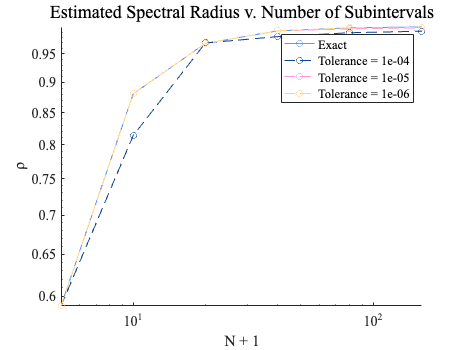

% Plot ρ versus (N + 1) for various tolerances
figure
default_style()

hold on
% Exact
plot(n_subintervals, spectral_radii, '-o', 'DisplayName', 'Exact')

% Estimated
for i = 1 : size(tolerances, 2)
    plot(n_subintervals, estimate_spectral_radii(i, :), '--o', 'DisplayName', sprintf('Tolerance = %1.0e', tolerances(i)));
end
hold off

set(gca, 'YScale', 'log', 'XScale', 'log');

ylabel('ρ')
xlabel('N + 1')
title({'Estimated Spectral Radius v. Number of Subintervals'}, 'FontWeight', 'normal', 'FontSize', 18)

legend()

### c.

errors_crank_nicholson = zeros(size(n_subintervals));

tolerance = 1e-8;

figure 
default_style()

hold on

% Plot analytic solution
xx = 0 : 1e-3 : L;
plot(xx, T_analytic(xx), 'magenta', 'LineWidth', 2, 'DisplayName', 'Analytic')

for j = 1 : size(n_subintervals, 2)
    n = n_subintervals(j) - 1;

    delta_t = 1/(4*n);              % ∆t/h << 1/2
    max_iterations = 2/delta_t;     % time = 2
    
    [A, B, c, h] = crank_nicholson_matrix(n, delta_t);
    
    A = lu_decompose_tridiagonal(A);
    T0 = zeros(n, 1) - 5;

    for k = 1 : max_iterations
        % Solve the system A * T(k+1) = B * T(k) + c
        b = B * T0 + c;
        T1 = forward_substitute(A, b);
        T1 = backward_substitute(A, T1);
        
        % Check if steady-state
        if max(abs(T1 - T0)) < tolerance
            fprintf(sprintf('Reached steady-state after %d iterations.\n', k));
            break;
        elseif k == max_iterations
            fprintf(sprintf('Reached maximum number of iterations: %d.\n', k));
        end
        
        T0 = T1;
    end
    
    % Plot the steady-state solution, T v. x
    xx = 0 : h : L;
    TT = [(Tc - Ta) T1.' (Ts - Ta)];

    plot(xx, TT, '--', 'LineWidth', 2, 'DisplayName', sprintf('N + 1 = %d', n + 1));

    % Calculate error
    errors_crank_nicholson(j) = max(abs(TT - T_analytic(xx)));
    % max(abs(TT - T_analytic(xx)))

end

Reached steady-state after 27 iterations.
Reached steady-state after 54 iterations.
Reached steady-state after 110 iterations.
Reached steady-state after 215 iterations.
Reached steady-state after 417 iterations.
Reached steady-state after 803 iterations.


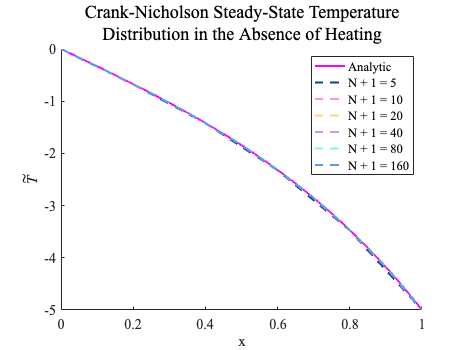


hold off

xlabel('x', 'Interpreter', 'latex')
ylabel('$\tilde{T}$', 'Interpreter', 'latex')
title({'Crank-Nicholson Steady-State Temperature', 'Distribution in the Absence of Heating'}, 'FontWeight', 'normal', 'FontSize', 18)

legend()

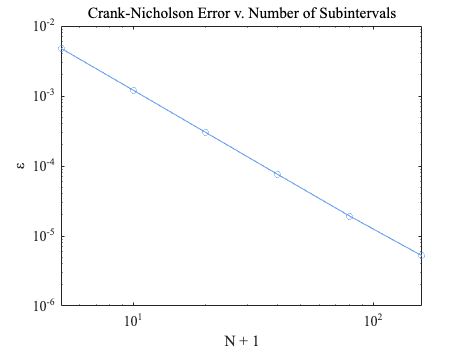

% Plot ε versus (N + 1) on a log-log scale
figure
default_style()

loglog(n_subintervals, errors_crank_nicholson, '-o')

ylabel('ε')
xlabel('N + 1')
title({'Crank-Nicholson Error v. Number of Subintervals'}, 'FontWeight', 'normal', 'FontSize', 18)

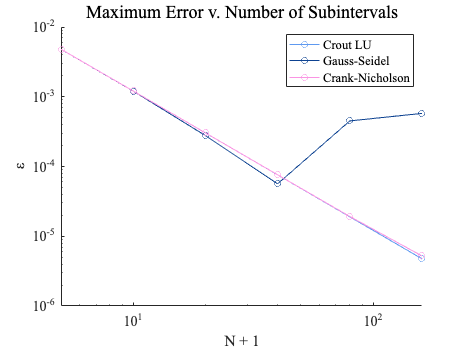

figure
default_style()

hold on
% Finite difference with Crout LU decomposition
plot(n_subintervals, errors_lu, '-o', 'DisplayName', 'Crout LU')

% Finite difference with Gauss-Seidel, lowest tolerance
plot(n_subintervals, errors_gauss_seidel(end, :), '-o', 'DisplayName', 'Gauss-Seidel');

% Crank-Nicholson "steady-state" solution
plot(n_subintervals, errors_crank_nicholson, '-o', 'DisplayName', 'Crank-Nicholson')
hold off

set(gca, 'YScale', 'log', 'XScale', 'log');

ylabel('ε')
xlabel('N + 1')
title({'Maximum Error v. Number of Subintervals'}, 'FontWeight', 'normal', 'FontSize', 18)

legend()

## Functions

%{
   Uses a Crank-Nicholson time-stepping algorithm to construct a system 
   Ax_(k+1) = Bx_k + c with n interior nodes for the bioheat BVP describing 
   the steady-state temperature distribution in the absence of heating.
%}

function [A, B, c, h] = crank_nicholson_matrix(n, delta_t)
    
    L = 1;
    lambda2 = 2.7;
    Ta = 37;
    Tc = 37;
    Ts = 32;

    A = zeros(n, n);
    B = zeros(n, n);

    c = zeros(n, 1);
    h = L / (n + 1);

    % Crank-Nicholson time-stepping algorithm
    for i = 1 : n
        A(i, i) = 2*h^2 + 2*delta_t + delta_t*h^2*lambda2;
        B(i, i) = 2*h^2 - 2*delta_t - delta_t*h^2*lambda2;
    
        if i < n
            A(i, i+1) = -delta_t;
            B(i, i+1) = delta_t;
        end

        if i > 1
            A(i, i-1) = -delta_t;
            B(i, i-1) = delta_t;
        end
    end

    % Boundary conditions
    c(1) = (Tc - Ta) * 2 * delta_t;
    c(n) = (Ts - Ta) * 2 * delta_t;

end

%{
   System of finite difference equations Ax = b with n interior nodes 
   for bioheat BVP describing the steady-state temperature distribution 
   in the absence of heating.
%}

function [A, b, h] = finite_difference_matrix(n)
    
    L = 1;
    lambda2 = 2.7;
    Ta = 37;
    Tc = 37;
    Ts = 32;

    A = zeros(n, n);
    b = zeros(n, 1);
    h = L / (n + 1);

    for i = 1 : n
        A(i, i) = -(2 + h^2 * lambda2);

        if i < n
            A(i, i+1) = 1;
        end

        if i > 1
            A(i, i-1) = 1;
        end
    end

    % Boundary conditions
    b(1) = -(Tc - Ta);
    b(n) = -(Ts - Ta);

end

%{
    Solves Ax = b for a tridiagonal matrix A by performing Crout LU decomposition on A. 
    Assumes A is at least 2x2.
    
    Returns:
        x: solution to Ax = b
%}

function x = solve_tridiagonal(A, b)
    % Decompose A
    A = lu_decompose_tridiagonal(A);

    % Solve Ly = b using forward substitution
    x = forward_substitute(A, b);

    % Solve Ux = y using backward substitution
    x = backward_substitute(A, x);

end

%{
    Performs Crout LU decomposition on A. 
    Assumes A is at least 2x2.
    
    Returns:
        A: Crout decomposition of A
%}

function A = lu_decompose_tridiagonal(A)

    n = size(A, 1);

    % U(1, 2) = A(1, 2) / L(1, 1)
    A(1, 2) = A(1, 2)/A(1, 1);

    for i = 2 : n-1
        % A(i, i-1) = L(i, i-1)

        % L(i, i) = A(i, i) - L(i, i-1) * U(i-1, i)
        A(i, i) = A(i, i) - A(i, i-1) * A(i-1, i); 

        % U(i, i+1) = A(i, i+1)/ L(i, i)
        A(i, i+1) = A(i, i+1) / A(i, i);
    end

    % L(n, n) = A(n, n) - L(n, n-1) * U(n-1, n)
    A(n, n) = A(n, n) - A(n, n-1) * A(n-1, n);

end

% Solves Ax = b using Gauss-Seidel iteration.
function [x_current, r] = gauss_seidel(A, b, T0, tolerance, max_iterations)
    x_previous = T0;
    x_current = T0;

    delta_previous = 0;
    delta_current = 0;

    r = 0;

    for k = 1 : max_iterations
        for i = 1 : size(x_current, 1)
            x_current(i) = (b(i) - A(i, 1:i-1) * x_current(1:i-1) - A(i, i+1:end) * x_current(i+1:end)) / A(i, i);
        end

        % L∞ relative norm stopping criterion 
        error = max(abs((x_current - x_previous) ./ x_current));

        delta_current = abs(x_current - x_previous);

        if error < tolerance
            fprintf('N + 1 = %d: Gauss-Seidel converged after %d iterations.\n', size(A,1)+1, k);
            % Estimate spectral radius 
            r = estimate_spectral_radius(delta_previous, delta_current);
            break;

        elseif k == max_iterations
            fprintf('N + 1 = %d: Gauss-Seidel reached maximum of %d iterations, error = %.5f\n', size(A,1)+1, max_iterations, error);
            r = estimate_spectral_radius(delta_previous, delta_current);

        end

        x_previous = x_current;
        delta_previous = delta_current;

    end

end

% Estimates the spectral radius of A.
function r = estimate_spectral_radius(delta_previous, delta_current)
    delta_previous_norm = sqrt(sum(abs(delta_previous .^ 2)));
    delta_current_norm = sqrt(sum(abs(delta_current .^ 2)));

    if delta_previous_norm ~= 0
        r = delta_current_norm / delta_previous_norm;
    else
        r = 0;
    end
end

% Calculates the spectral radius of A.
function r = spectral_radius(A)
    
    n = size(A, 1);

    % T = -(D + L)^-1 * U
    T = -forward_substitute(tril(A), eye(n)) * triu(A, 1);
    r = max(abs(eig(T)));
end

% Solves Lx = b with forward substitution.
function x = forward_substitute(A, b)
    for i = 1 : size(A, 1)
        b(i, :) = (b(i, :) - A(i, 1:i-1) * b(1:i-1, :)) / A(i, i);
    end

    x = b;
end

% Solves Ux = b with backward substitution.
% Assumes diagonal entries A(i, i) = 1.
function x = backward_substitute(A, b)
    n = size(A, 1);
    
    for i = n : -1 : 1
        b(i, :) = (b(i, :) - A(i, i+1:n) * b(i+1:n, :));
    end

    x = b;
end

function default_style()
    color_order = [0.37 0.60 0.94
                   0.05 0.26 0.57
                   0.98 0.58 0.89
                   0.99 0.82 0.54
                   0.81 0.59 0.95
                   0.53 0.98 0.84];
    
    colororder(color_order)

    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 14)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 16)
end
